# Feedforward neural network architecture search

tic

Data Preparation

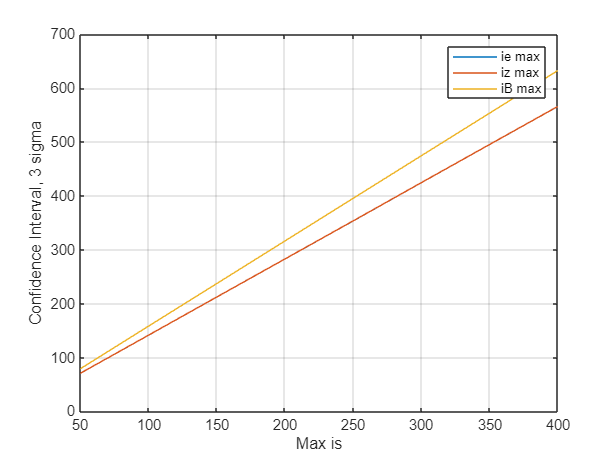

beta =    -0.0284
    1.4144


ie_max = 353.5621

ie_max = 353.3280

beta =    -0.0558
    1.4146


iz_max = 353.5896

iz_max = 353.4193

beta =     0.0552
    1.5807


iB_max = 395.2333

iB_max = 395.2787

Von_max = 6000

vc_ref = 18000

E = 8.9100e+05

VB = 12000

IB = 400

IE = 375

Nbuffer_variables = 32

Nsamples = 100000

Ninputs = 27

Noutputs = 5

ans =           27      100000


ans =            5      100000


Ninputs = 27

Nsamples = 100000

Noutputs = 5

Nsamples = 100000

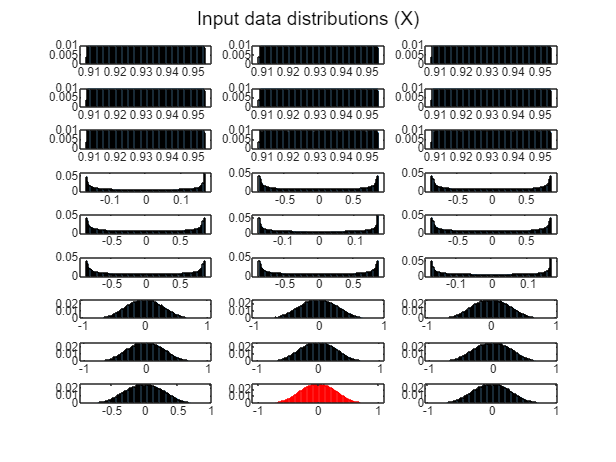

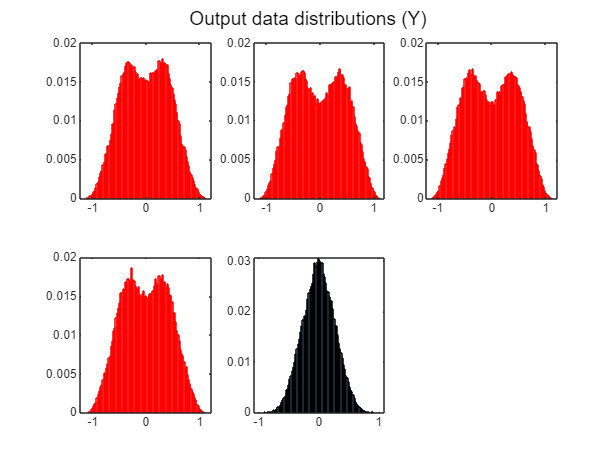

run("Simulations\DataPreparation.mlx")

PERFORM SEARCH (CAREFUL)

perform_search = false;

Architecture search

% % Crear carpetas para guardar los resultados
% mkdir('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Architectures');
% mkdir('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance');

% Definir rango de arquitecturas

env = classM3C()

env =   classM3C with properties:

                    Tf: 0.5000
                    Ts: 2.0000e-05
                    Ti: 1.0000e-04
                Ti_idx: 5
                    Tl: 1.0000e-04
                Tl_idx: 5
                    Ax: 7000
                   fxi: 50
                   wx0: 314.1593
                    Ay: 5000
                   fyi: 30
                   wy0: 188.4956
                     A: [6×9 double]
                 pinvA: [9×6 double]
                     m: 9
                     N: [9×4 double]
                 pinvN: [4×9 double]
                     C: 0.0200
                     L: 0.0200
                     R: 1.0000e-03
               Tabc_ab: [2×3 double]
               Tab_abc: [3×2 double]
      Tabc_dq_function: @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]
               Vxy_max: 12000
               Von_max: 6000
                Is

Ninputs = env.getObservationInfo.Dimension(1)

Ninputs = 27

Noutputs = env.getActionInfo.Dimension(1)

Noutputs = 5


Nlayers_range = 1:3

Nlayers_range =      1     2     3


Nneurons_range = round(Ninputs/2):5:3*Ninputs

Nneurons_range =     14    19    24    29    34    39    44    49    54    59    64    69    74    79



if perform_search
% Inicializar matrices para guardar resultados
results = [];

% Iterar sobre el rango de arquitecturas
for Nlayers = Nlayers_range
    for Nneurons = Nneurons_range
        try
            net_name = [num2str(Nlayers) 'L' num2str(Nneurons) 'N'];

            NNgenerator_args = struct();
            NNgenerator_args.Ninputs = Ninputs;
            NNgenerator_args.Noutputs = Noutputs;
            NNgenerator_args.NFFlayers = Nlayers;
            NNgenerator_args.NRlayers = 0;
            NNgenerator_args.NFFneurons = Nneurons;
            NNgenerator_args.Nwindow = 1;
            NNgenerator_args.hidden_activation = 'reluLayer';
            NNgenerator_args.output_activation = 'tanhLayer';
            NNgenerator_args.dropout = 0;
            NNgenerator_args.WinitFcn = 'narrow-normal';
            NNgenerator_args.BinitFcn = 'narrow-normal';
            NNgenerator_args.train_bias = false;
            NNgenerator_args.scale_data = false;
            NNgenerator_args.Xmax = Xmax;
            NNgenerator_args.Ymax = Ymax;
            
            FFnet = NNgenerator(NNgenerator_args);
            FFnet = dlupdate(@double, FFnet);

            % Training
            NNtrain_args = struct();
            NNtrain_args.net = FFnet;
            NNtrain_args.X_train = dlX_tr;
            NNtrain_args.Y_train = dlY_tr;
            NNtrain_args.X_val = dlX_val;
            NNtrain_args.Y_val = dlY_val;
            NNtrain_args.regularization = 0;
            NNtrain_args.lr_i = 1e-2;
            NNtrain_args.lr_f = 1e-6;
            NNtrain_args.plots = 'none';
            
            FFnet = NNtrain(NNtrain_args);

            % Evaluating
            trainPerformance = mse(FFnet.predict(dlX_tr), dlY_tr);
            valPerformance = mse(FFnet.predict(dlX_val), dlY_val);
            diffPerformance = valPerformance - trainPerformance;

            % Results
            results(end+1, :) = [Nlayers, Nneurons, trainPerformance, valPerformance, diffPerformance];

            % Save net
            save(fullfile('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Architectures', ['A' net_name '.mat']), 'FFnet');

        catch ME
            disp(['Error ' net_name ': ' ME.message]);
            continue;
        end
    end
end
csvwrite('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance/performance.csv', results);

end

Heatmap

data = readmatrix('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance/performance.csv');
Narchitectures = size(data, 1)

Narchitectures = 42

Nlayers_range = sort(unique(data(:, 1)))'

Nlayers_range =      1     2     3


Nneurons_range = sort(unique(data(:, 2)))'

Nneurons_range =     14    19    24    29    34    39    44    49    54    59    64    69    74    79


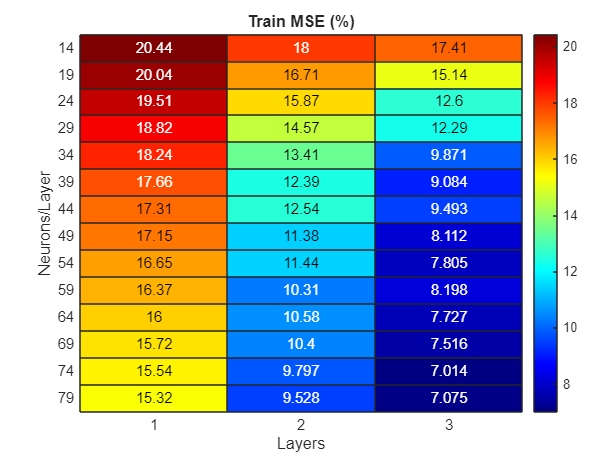


% Performance in percentage
trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;

z_max = 100;
trainPerformance(trainPerformance > z_max) = z_max;
valPerformance(valPerformance > z_max) = z_max;

figure;
heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train MSE (%)');
colorbar;
colormap jet;

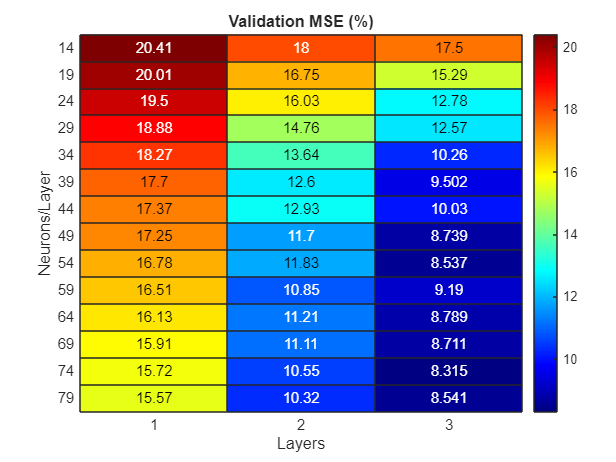


figure;
heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Validation MSE (%)');
colorbar;
colormap jet;

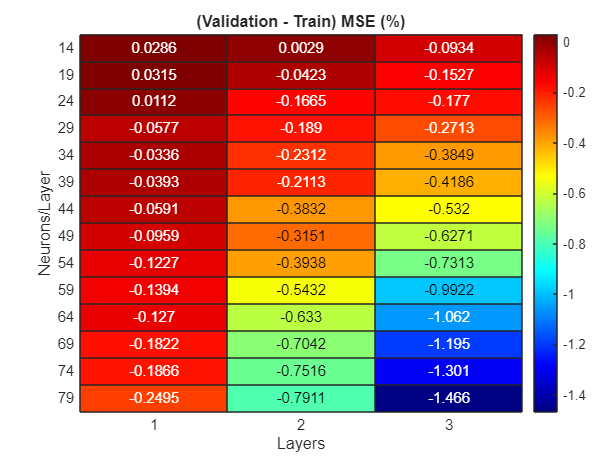


figure;
heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('(Validation - Train) MSE (%)');
colorbar;
colormap jet;

3d Plot

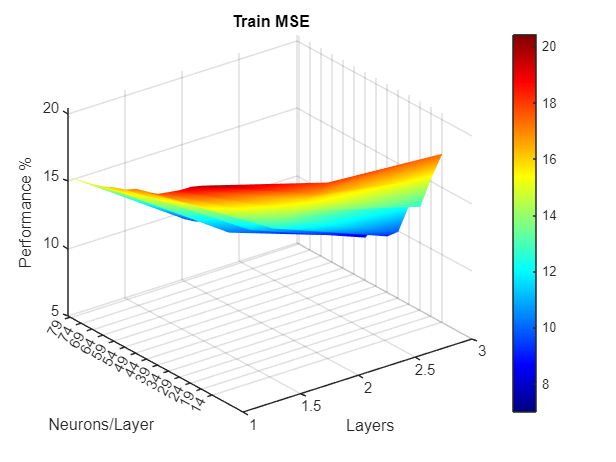

figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Train MSE');
colorbar;
colormap jet;
shading interp;

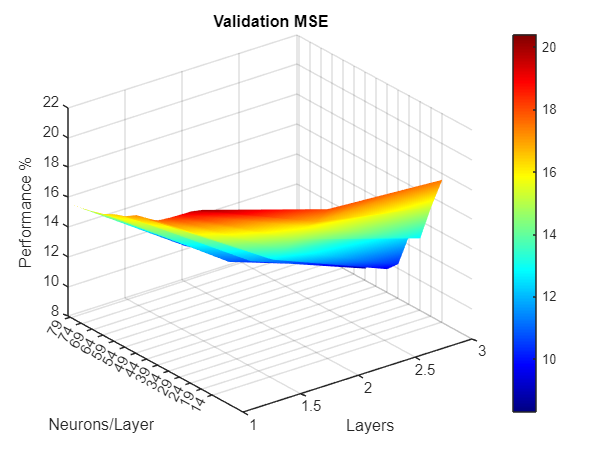


figure;
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Validation MSE');
colorbar;
colormap jet;
shading interp;

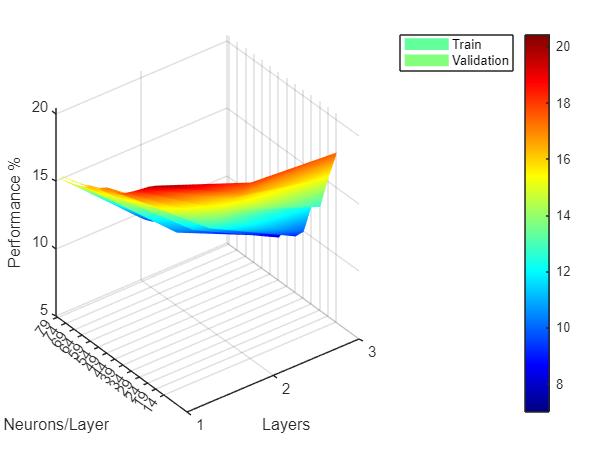


figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
hold on
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
hold off

xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
legend(["Train", "Validation"])
colorbar;
colormap jet;
shading interp;

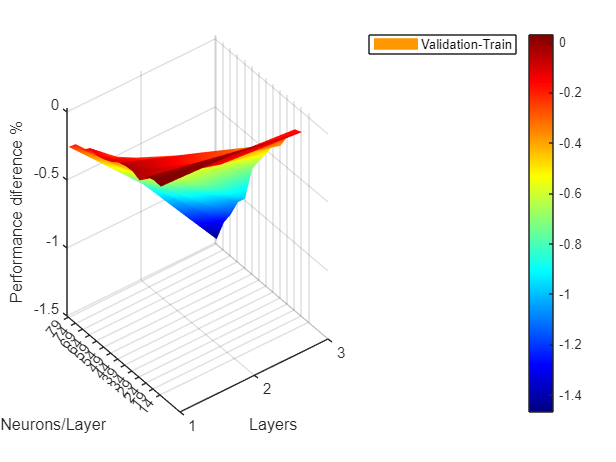


figure;
surf(Nlayers_range, Nneurons_range, diffPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance diference %');
legend("Validation-Train")
colorbar;
colormap jet;
shading interp;

## Tables

From saved performances

Nbest_architectures = 4;

valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
[valid_rows, valid_cols] = find(valid_idx);

sort(unique(valid_rows))'

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14


sort(unique(valid_cols))'

ans =      1     2     3



results_table = [];
for i = 1:length(valid_rows)
    row = valid_rows(i);
    col = valid_cols(i);

    mse_train = trainPerformance(row, col);
    mse_val = valPerformance(row, col);
    mse_diff = abs(diffPerformance(row, col));

    results_table = [results_table; col, (row-1)*5+round(Ninputs/2), mse_train, mse_val, mse_diff];
end

train_table = sortrows(results_table, 3);
validation_table = sortrows(results_table, 4);
diff_table = sortrows(results_table, 5);

train_table = train_table(1:Nbest_architectures, :);
validation_table = validation_table(1:Nbest_architectures, :);
diff_table = diff_table(1:Nbest_architectures, :);

train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});

disp('Tabla de mejores rendimientos en entrenamiento:');

Tabla de mejores rendimientos en entrenamiento:


disp(train_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Diff 
    ______    _____________    ______    _______    ______
      3            74          7.0144     8.315     1.3006
      3            79           7.075    8.5414     1.4664
      3            69          7.5159     8.711     1.1951
      3            64           7.727     8.789      1.062



disp('Tabla de mejores rendimientos en validación:');

Tabla de mejores rendimientos en validación:


disp(validation_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Diff  
    ______    _____________    ______    _______    _______
      3            74          7.0144     8.315      1.3006
      3            54          7.8053    8.5365     0.73125
      3            79           7.075    8.5414      1.4664
      3            69          7.5159     8.711      1.1951



disp('Tabla de mejores diferencias entre entrenamiento y validación:');

Tabla de mejores diferencias entre entrenamiento y validación:


disp(diff_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val      Diff   
    ______    _____________    ______    _______    _________
      2            14          17.998    17.995     0.0029094
      1            24          19.514    19.502      0.011192
      1            14           20.44    20.412      0.028611
      1            19          20.038    20.006      0.031489


Performance using the net

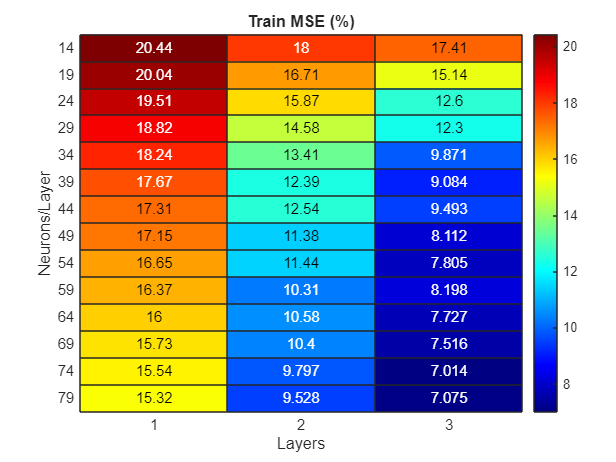

i = 1;
for Nlayers = Nlayers_range
    for Nneurons = Nneurons_range
        load(['NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Architectures/A' num2str(Nlayers) 'L' num2str(Nneurons) 'N.mat'], 'FFnet');
        trainPerformance = mse(FFnet.predict(dlX_tr), dlY_tr);
        valPerformance = mse(FFnet.predict(dlX_val), dlY_val);
        diffPerformance = (valPerformance - trainPerformance);
        data(i, 3) = trainPerformance;
        data(i, 4) = valPerformance;
        data(i, 5) = diffPerformance;
        i = i + 1;
    end
end

% Performance in percentage
trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;

z_max = 100;
trainPerformance(trainPerformance > z_max) = z_max;
valPerformance(valPerformance > z_max) = z_max;

figure;
heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train MSE (%)');
colorbar;
colormap jet;

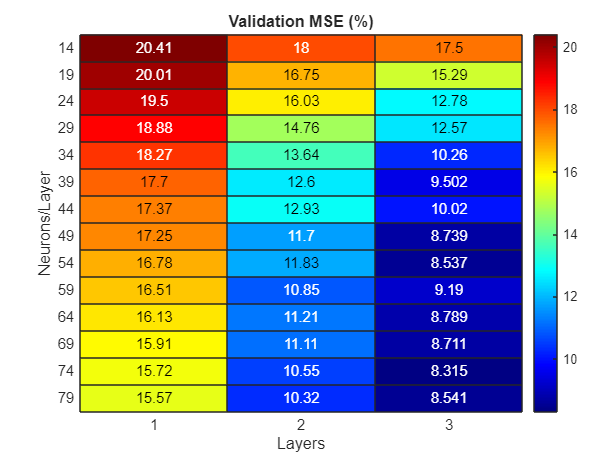


figure;
heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Validation MSE (%)');
colorbar;
colormap jet;

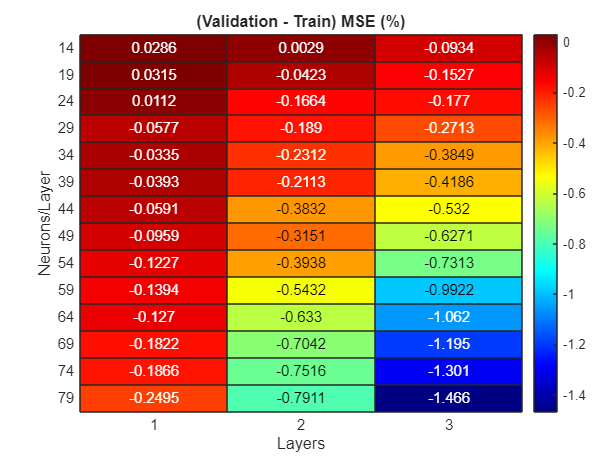


figure;
heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('(Validation - Train) MSE (%)');
colorbar;
colormap jet;

Tables

Nbest_architectures = 4;

valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
[valid_rows, valid_cols] = find(valid_idx);

results_table = [];
for i = 1:length(valid_rows)
    row = valid_rows(i);
    col = valid_cols(i);

    mse_train = trainPerformance(row, col);
    mse_val = valPerformance(row, col);
    mse_diff = abs(diffPerformance(row, col));

    results_table = [results_table; col, row*2, mse_train, mse_val, mse_diff];
end

train_table = sortrows(results_table, 3);
validation_table = sortrows(results_table, 4);
diff_table = sortrows(results_table, 5);

train_table = train_table(1:Nbest_architectures, :);
validation_table = validation_table(1:Nbest_architectures, :);
diff_table = diff_table(1:Nbest_architectures, :);

train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});

disp('Tabla de mejores rendimientos en entrenamiento:');

Tabla de mejores rendimientos en entrenamiento:


disp(train_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Diff 
    ______    _____________    ______    _______    ______
      3            26          7.0144     8.315     1.3006
      3            28           7.075    8.5414     1.4664
      3            24          7.5159     8.711     1.1951
      3            22           7.727     8.789      1.062



disp('Tabla de mejores rendimientos en validación:');

Tabla de mejores rendimientos en validación:


disp(validation_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Diff  
    ______    _____________    ______    _______    _______
      3            26          7.0144     8.315      1.3006
      3            18          7.8053    8.5365     0.73125
      3            28           7.075    8.5414      1.4664
      3            24          7.5159     8.711      1.1951



disp('Tabla de mejores diferencias entre entrenamiento y validación:');

Tabla de mejores diferencias entre entrenamiento y validación:


disp(diff_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val      Diff   
    ______    _____________    ______    _______    _________
      2             2          17.998    17.995     0.0029094
      1             6          19.514    19.502      0.011192
      1             2           20.44    20.412      0.028611
      1             4          20.038    20.006      0.031489


toc

Elapsed time is 27.932341 seconds.
